% =========================================================
%  Linear Classification by Simple Perceptron
%  Binary classification: labels must be +1 or -1
% =========================================================

clc; clear; close all;

%% --- 1. Generate linearly separable training data ---
rng(42);                          % reproducibility

n = 60;                           % samples per class
% Class +1  (upper-right cluster)
X1 = [randn(n,1)+2, randn(n,1)+2];
% Class -1  (lower-left cluster)
X2 = [randn(n,1)-2, randn(n,1)-2];

X = [X1; X2];                     % feature matrix  [2n x 2]
y = [ones(n,1); -ones(n,1)];      % labels           [2n x 1]

% Shuffle the dataset
idx  = randperm(2*n);
X    = X(idx,:);
y    = y(idx);

%% --- 2. Perceptron parameters ---
lr          = 0.1;       % learning rate
max_epochs  = 100;       % maximum passes over the data
[m, d]      = size(X);   % m = samples, d = features

% Initialise weights and bias to zero
w = zeros(d, 1);         % weight vector  [d x 1]
b = 0;                   % bias scalar

%% --- 3. Training loop ---
errors_per_epoch = zeros(max_epochs, 1);

for epoch = 1:max_epochs
    num_errors = 0;

    for i = 1:m
        % Compute linear activation
        z         = X(i,:) * w + b;   % dot product + bias
        % Hard-threshold activation: sign function (+1 or -1)
        y_hat     = sign(z);
        if y_hat == 0, y_hat = 1; end % treat 0 as +1

        % Perceptron update rule (only fires on misclassification)
        if y_hat ~= y(i)
            w = w + lr * y(i) * X(i,:)';
            b = b + lr * y(i);
            num_errors = num_errors + 1;
        end
    end

    errors_per_epoch(epoch) = num_errors;

    % Early stopping: converged when no misclassifications
    if num_errors == 0
        fprintf('Converged at epoch %d\n', epoch);
        errors_per_epoch = errors_per_epoch(1:epoch);
        break;
    end
end

Converged at epoch 2



%% --- 4. Evaluate on training data ---
y_pred  = sign(X * w + b);
y_pred(y_pred == 0) = 1;
accuracy = sum(y_pred == y) / m * 100;
fprintf('Training accuracy: %.1f%%\n', accuracy);

Training accuracy: 100.0%


fprintf('Final weights: w = [%.4f, %.4f],  b = %.4f\n', w(1), w(2), b);

Final weights: w = [0.2460, 0.3396],  b = 0.0000


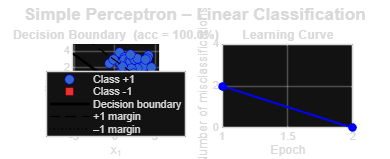


%% --- 5. Visualisation ---
figure('Name','Simple Perceptron – Linear Classification', ...
       'Color','white','Position',[100 100 1100 450]);

% --- 5a. Decision boundary plot ---
subplot(1,2,1); hold on; grid on;
axis equal;

% Scatter plot – colour by true label
plot(X(y== 1,1), X(y== 1,2), 'bo', ...
     'MarkerSize',7, 'MarkerFaceColor',[0.2 0.4 0.8], 'DisplayName','Class +1');
plot(X(y==-1,1), X(y==-1,2), 'rs', ...
     'MarkerSize',7, 'MarkerFaceColor',[0.9 0.2 0.2], 'DisplayName','Class -1');

% Decision boundary: w1*x1 + w2*x2 + b = 0  =>  x2 = -(w1*x1+b)/w2
x1_range = linspace(min(X(:,1))-1, max(X(:,1))+1, 200);
if abs(w(2)) > 1e-8
    x2_boundary = -(w(1)*x1_range + b) / w(2);
    plot(x1_range, x2_boundary, 'k-', 'LineWidth', 2, 'DisplayName','Decision boundary');

    % Margin lines (w·x + b = ±1) for visual reference
    x2_pos = -(w(1)*x1_range + b - 1) / w(2);
    x2_neg = -(w(1)*x1_range + b + 1) / w(2);
    plot(x1_range, x2_pos, 'k--', 'LineWidth', 1, 'DisplayName','+1 margin');
    plot(x1_range, x2_neg, 'k:', 'LineWidth', 1, 'DisplayName','–1 margin');
end

xlabel('x_1'); ylabel('x_2');
title(sprintf('Decision Boundary  (acc = %.1f%%)', accuracy));
legend('Location','best','FontSize',8);
xlim([min(X(:,1))-1, max(X(:,1))+1]);
ylim([min(X(:,2))-1, max(X(:,2))+1]);

% --- 5b. Learning curve ---
subplot(1,2,2);
plot(1:numel(errors_per_epoch), errors_per_epoch, 'b-o', ...
     'LineWidth',1.5, 'MarkerSize',5, 'MarkerFaceColor','b');
xlabel('Epoch'); ylabel('Number of misclassifications');
title('Learning Curve'); grid on;
xlim([1, numel(errors_per_epoch)]);
ylim([0, max(errors_per_epoch)+2]);

sgtitle('Simple Perceptron – Linear Classification', 'FontSize',13,'FontWeight','bold');


%% --- 6. Helper: predict new samples ---
function label = perceptron_predict(X_new, w, b)
    % Classify new samples using trained weights.
    % Inputs:  X_new  [n x d] feature matrix
    %          w      [d x 1] weight vector
    %          b      scalar bias
    % Output:  label  [n x 1] predicted labels (+1 or -1)
    z     = X_new * w + b;
    label = sign(z);
    label(label == 0) = 1;
end